#  Sistemas Realimentados - Trabalho 1 

Nome: Luiza Batista Laquini (2019107786)

**Data limite para entrega:14/9, meia-noite**.

**Referências para este trabalho além das notas de aula:**

- [Manual rápido do Matlab](https://drive.google.com/file/d/1_mXyft7ynFmkxGnCyx7BV8VyOKyIx9tj/view?usp=share_link)

- [Resposta transitória e estacionária](https://drive.google.com/file/d/19GToHEkcvTon0UK2nOmi1_l0k5dx3YIJ/view?usp=share_link)

**Inicialização:**

I=20; % Seu valor de I
[Y,G1,G2]=init_t1(I);
datetime('now')

ans = datetime
   15-Sep-2023 00:54:32


warning off

**I) Relação entre resposta ao degrau e modelos**

Observe nas figuras 1,2,3 a resposta ao degrau unitário dos modelos g1, g2, g3.

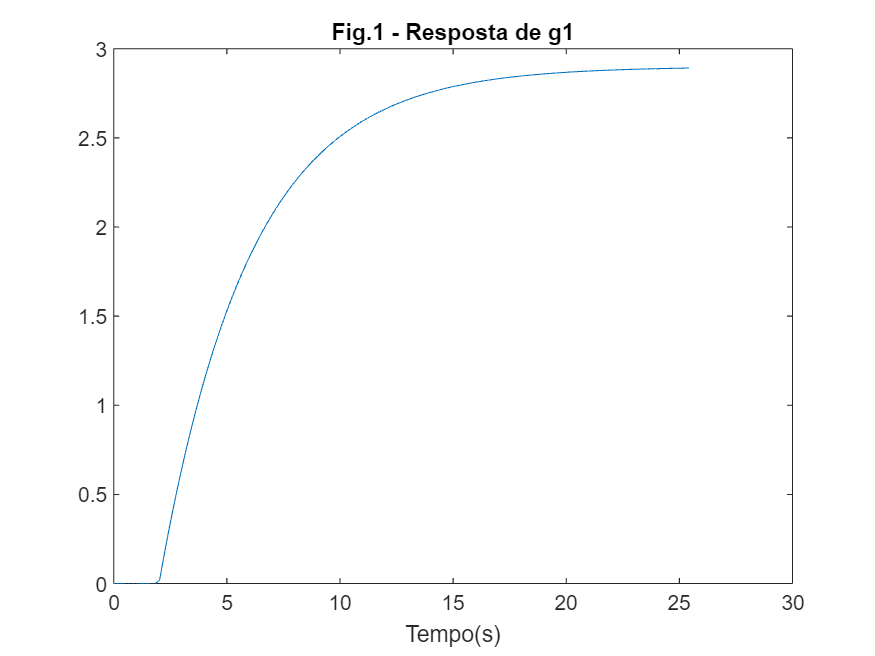

figure;plot(Y(1).t,Y(1).y);title('Fig.1 - Resposta de g1');xlabel('Tempo(s)');

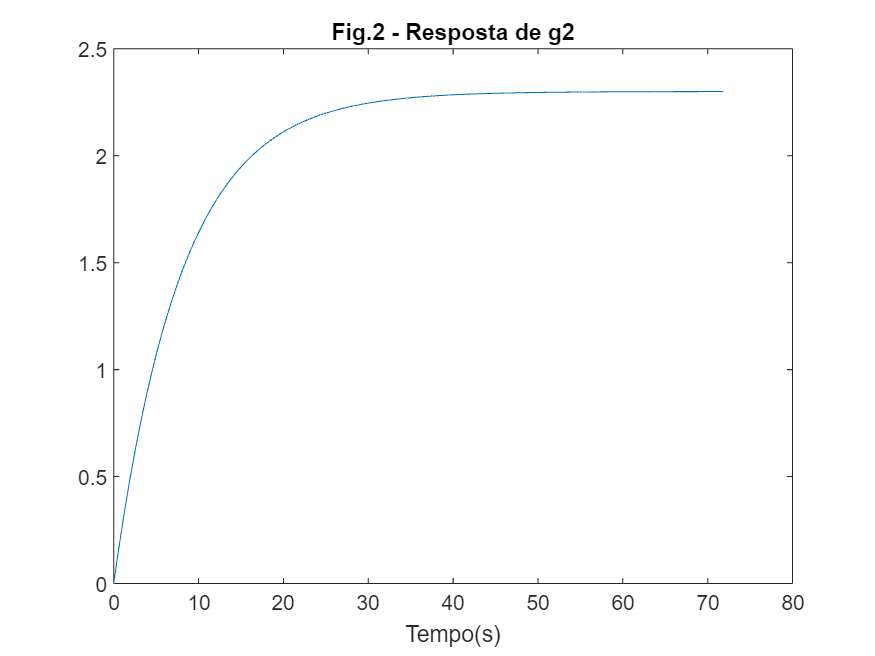

figure;plot(Y(2).t,Y(2).y);title('Fig.2 - Resposta de g2');xlabel('Tempo(s)');

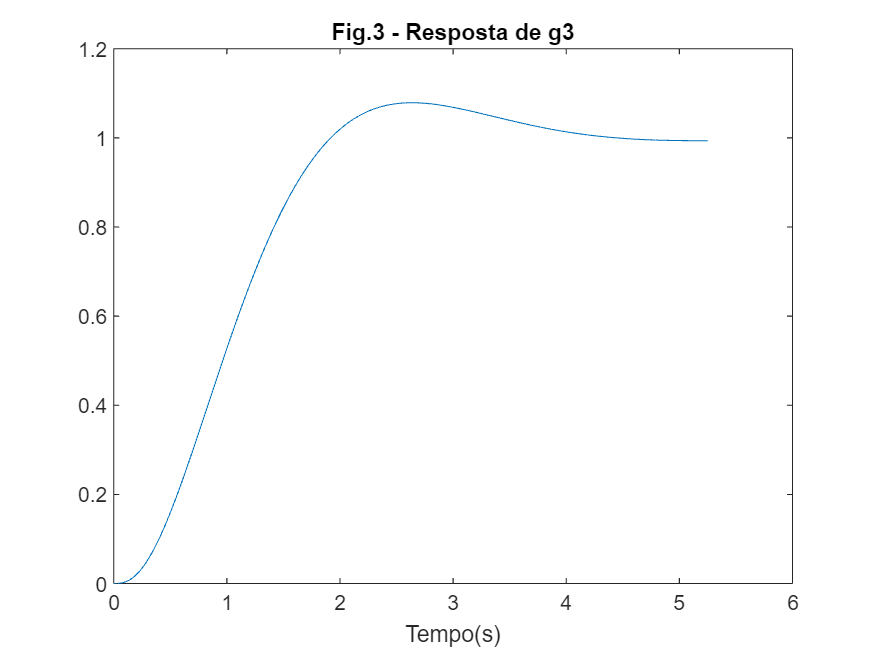

figure;plot(Y(3).t,Y(3).y);title('Fig.3 - Resposta de g3');xlabel('Tempo(s)');

1) Obtenha os modelos g1,g2,g3 que geraram estas respostas ao degrau, defina-os abaixo e compare com as curvas fornecidas usando os comandos dados.

Para isso, devemos primeiro identificar os parâmetros e a ordem da função para, enfim, montarmos as malhas do sistema, sendo:

$M(s)=\frac{K}{\tau s+1}$  , para sistemas de primeira ordem sem tempo morto;

$M(s)=\frac{K}{\tau s+1}.e^{- \theta s}$  , para sistemas de primeira ordem com tempo morto; e

$M(s)=\frac{\omega n^2}{s^2 + 2 \zeta \omega n s +\omega n ^2}$  , para sistemas de segunda ordem.

% g1 (valores aproximados)
% tempo morto = 2,2s 
% constante de tempo = 6 - 2,2 = 3,8s 
% ts = 17,5s
% K = 2,9
% ordem 1
g1=tf(2.9,[3.8 1]);
g1.InputDelay=2.2

g1 =
 
                   2.9
  exp(-2.2*s) * ---------
                3.8 s + 1
 
Continuous-time transfer function.
Model Properties


% g2 (valores aproximados)
% constante de tempo = 8s
% ts = 32s
% K = 2,3
% ordem 1
% não há tempo morto
g2=tf(2.3,[8 1]);
g2

g2 =
 
    2.3
  -------
  8 s + 1
 
Continuous-time transfer function.
Model Properties


% g3 (valores aproximados)
% constante de tempo = 1,1s
% K = 1
ts = 4.1;
% ordem 2
up = 8;
a=log(up/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(ts*zeta);

g3=tf(wn^2, [1 2*zeta*wn wn^2]);
g3

g3 =
 
          2.424
  ---------------------
  s^2 + 1.951 s + 2.424
 
Continuous-time transfer function.
Model Properties


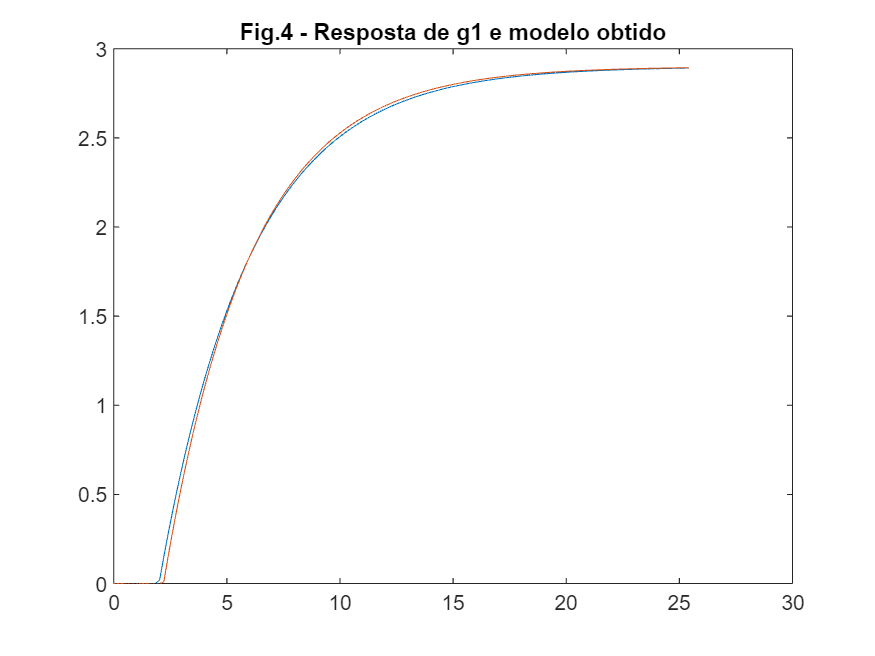

% Comparações das respostas com os modelos obtidos:
y1=step(g1,Y(1).t);
y2=step(g2,Y(2).t);
y3=step(g3,Y(3).t);
figure;plot(Y(1).t,Y(1).y,Y(1).t,y1);title('Fig.4 - Resposta de g1 e modelo obtido');

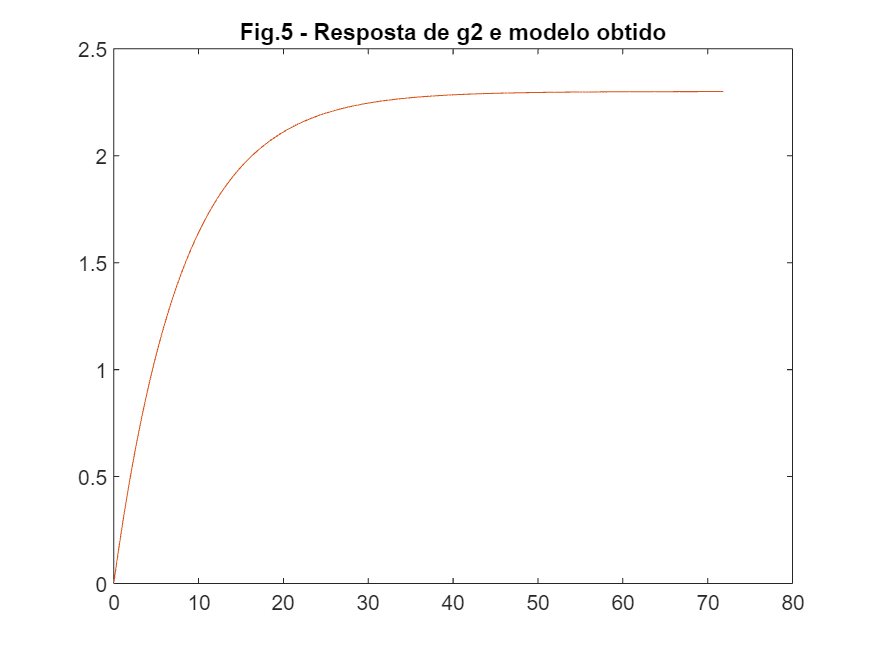

figure;plot(Y(2).t,Y(2).y,Y(2).t,y2);title('Fig.5 - Resposta de g2 e modelo obtido');

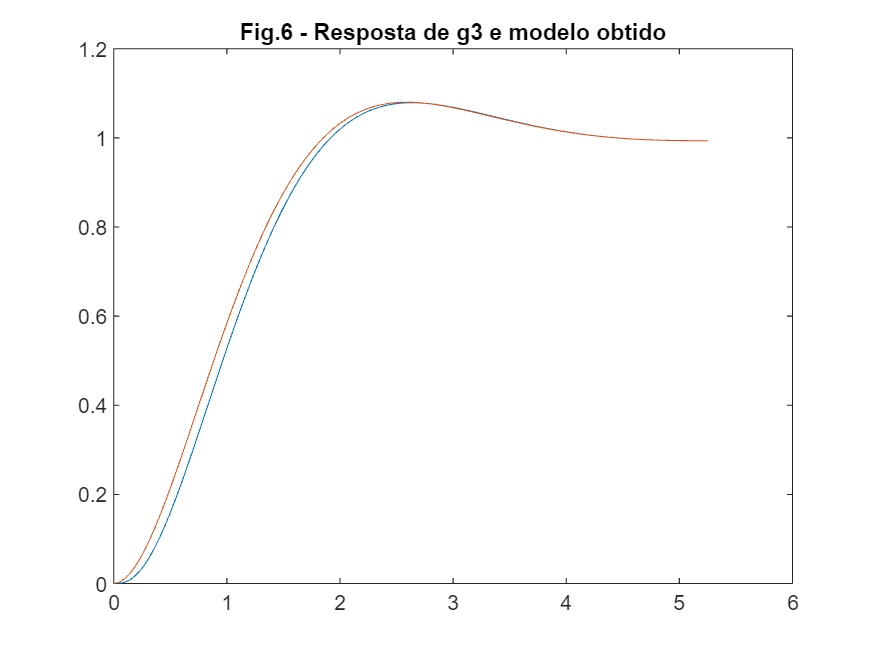

figure;plot(Y(3).t,Y(3).y,Y(3).t,y3);title('Fig.6 - Resposta de g3 e modelo obtido');

**II) Desempenho em função do ganho K**. 

Seja a função de transferência G1 já definida.

Os comandos abaixo permitem obter os vários parâmetros de desempenho em malha fechada quando o ganho K varia. **Escolha kmax **de modo que todos gráficos mostrem claramente o efeito do ganho em cada parâmetro. Sugestão: escolha kmax de modo que UP vá de 0 a 60%.

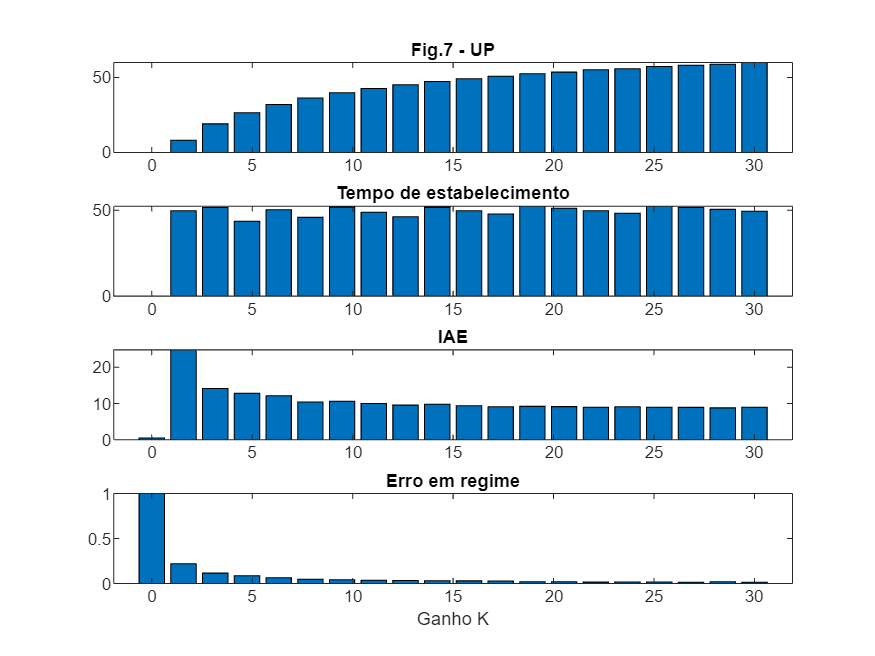

kmax=30; % Escolher valor adequado para kmax
up=[];ts=[];iae=[];erro=[];

K=linspace(0,kmax,20);
for i=1:length(K)
    m=feedback(K(i)*G1,1);
    S=stepinfo(m);
    [y,t]=step(m);
    up=[up;S.Overshoot];
    ts=[ts;S.SettlingTime];
    iae=[iae;trapz(t,abs(1-y))];
    erro=[erro;1-y(end)];
end
figure;
subplot(4,1,1);bar(K,up);title('Fig.7 - UP');
subplot(4,1,2);bar(K,ts);title('Tempo de estabelecimento');
subplot(4,1,3);bar(K,iae);title('IAE');
subplot(4,1,4);bar(K,erro);title('Erro em regime');xlabel('Ganho K');

2.1 Escolha o ganho K para o qual considera que houve uma boa resposta, informando o ganho K, UP, ts, IAE e o erro em regime correspondentes.

K = 4.73684; UP = 26.53%; ts = 43.6165s; IAE = 12.8599; Erro em regime = 0.0862151

Considero que essa é uma boa resposta, pois, dentre as possibilidades, é a mais rápida possível (menor ts), com IAE e erro em regime satisfatórios. Apenas o sobressinal que ficou um pouco elevado, mas, para um sobressinal menor que este escolhido, o tempo de estabelecimento, IAE e erro em regime já pioram demasiado. 

Lembrando que essa foi uma escolha no modo geral, mas que, dependendo da aplicação, a melhor opção poderia ser diferente. 

2.2 Feche a malha com este ganho K, obtenha os polos de malha fechada e mostre que a resposta ao degrau é a especificada.

K=4.73684; % K escolhido
T=feedback(K*G1,1); % fecha a malha 
polos_mf=pole(T); % obtém os polos
polos_mf

polos_mf =   -0.0750 + 0.1776i
  -0.0750 - 0.1776i


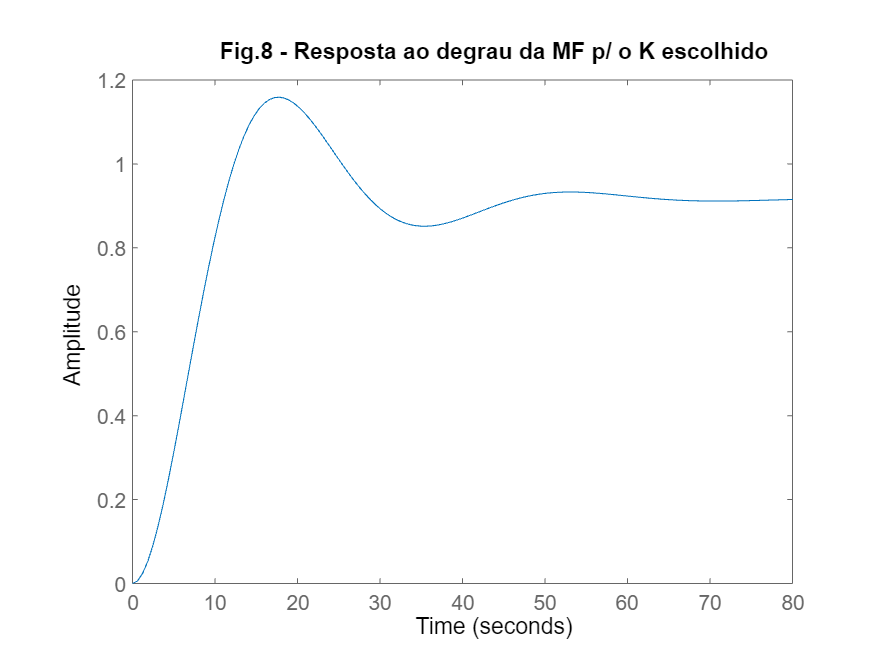

figure;step(T);title('Fig.8 - Resposta ao degrau da MF p/ o K escolhido');

Os valores anteriormente obtidos (UP = 26.53%; ts = 43.6165s; IAE = 12.8599; Erro em regime = 0.0862151) são observados na resposta acima e também na 'stepinfo' a seguir:

stepinfo(T)

ans = struct with fields:
         RiseTime: 7.5091
    TransientTime: 43.6165
     SettlingTime: 43.6165
      SettlingMin: 0.8515
      SettlingMax: 1.1589
        Overshoot: 26.5310
       Undershoot: 0
             Peak: 1.1589
         PeakTime: 17.8067


2.3 Calcule à mão o erro em regime usando G1 e o ganho K selecionado em 2.1, e compare com o valor obtido no gráfico na Fig7.

Sendo G1:

G1 % visualizar G1 já definida

G1 =
 
         2.3
  ------------------
  320 s^2 + 48 s + 1
 
Continuous-time transfer function.
Model Properties


O erro é obtido com:


$$e_{\textrm{ss}} =\lim_{s\to 0} \;\frac{s\;R\left(s\right)}{1+K\ldotp \textrm{G1}}$$


$e_{\textrm{ss}} =\lim_{s\to 0} \;\frac{s}{1+K\ldotp \textrm{G1}}\cdot \frac{1}{s}$  , onde 1/s é a entrada degrau unitário


$$e_{\textrm{ss}} =\lim_{s\to 0} \;\frac{s}{1+4\ldotp 73684\;\frac{2\ldotp 3}{320s^2 +48s+1}}\cdot \frac{1}{s}$$



$$e_{\textrm{ss}} =\lim_{s\to 0} \;\frac{1}{1+4\ldotp 73684\;\frac{2\ldotp 3}{320s^2 +48s+1}}$$



$$e_{\textrm{ss}} =\lim_{s\to 0} \;\frac{1}{1+\frac{10\ldotp 894732}{320s^2 +48s+1}}$$



$$e_{\textrm{ss}} =\frac{1}{1+10\ldotp 894732\;}$$



$$e_{\textrm{ss}} \cong 0\ldotp 084$$


O valor obtido à mão coincide com o valor obtido no gráfico da Figura 7.

**III) Projeto de controlador PID via métodos de sintonia baseados na resposta ao degrau**

Use o método de sintonia Ziegler-Nichols e projete controladores C(s) da forma P, PI e PID para G2 já definida.

G2 % visualizar G2 já definida

G2 =
 
                 2.7
  exp(-15*s) * --------
               30 s + 1
 
Continuous-time transfer function.
Model Properties


Nota-se que G2 é uma FT de primeira ordem com tempo morto (foptd). Agora vamos confirmar os métodos possíveis de utilização:

help pidtuning 

  function [C, iae, c, P ] = pidtuning(varargin)
  Date: 17/6/2023   prof. Celso J. Munaro (DEE-CT-UFES)
  
  Inputs:
  G: model obtained via tf commad: foptd, first ordem, second order (real or complex poles)
  Models, methods, types
  ----------------------------------------------------------------
  |  Model G | Methods             | Types    | Parameters       |
  |--------------------------------------------------------------|
  |  foptd   | zie,chr,chr20,cohen | P,PI,PID |     -            |
  |  foptd   | iaeot               | PI, PID  |     -            |
  |  foptd   | lambda              | PI, PID  |  lambda          |
  |  order 1 | lambda              | PI       |  lambda          |
  |  order 1 | polealoc            | PI       |  UP,ts           |
  |  order 2 | lambda              | PID      |  lambda          |
  |  order 2 | polealoc            | PI       |  UP,ts           |
  |--------------------------------------------------------------|
  
  Parameters:
  lambda : 

% Conforme pedido, utilizaremos Ziegler-Nichols (zie), possível para foptd
cp=pidtuning(G2,'method','zie','type','P'); % obtendo controle P
cpi=pidtuning(G2,'method','zie','type','PI'); % obtendo controle PI
cpid=pidtuning(G2,'method','zie','type','PID'); % obtendo controle PID

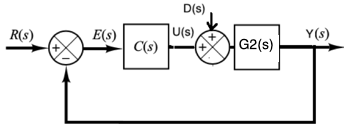

3.1) Compare a resposta ao degrau Y(s)/R(s) de cada controlador em termos de UP, ts, erro em regime, plotando a resposta de P,PI,PID na mesma figura.

G2P=pade(G2,2); % G2 após aproximação de Padé de segunda ordem

Observação: O controlador PID inclui a ação derivativa, que pode aumentar a sensibilidade ao tempo morto - gerando uma resposta instável - especialmente se o ganho derivativo for alto. Por isso, na hora de fechar a malha para o controle PID, será necessário usar G2 com a aproximação de Padé. O mesmo não é necessário para P e PI, pois estes não possuem ganho derivativo (Kd).

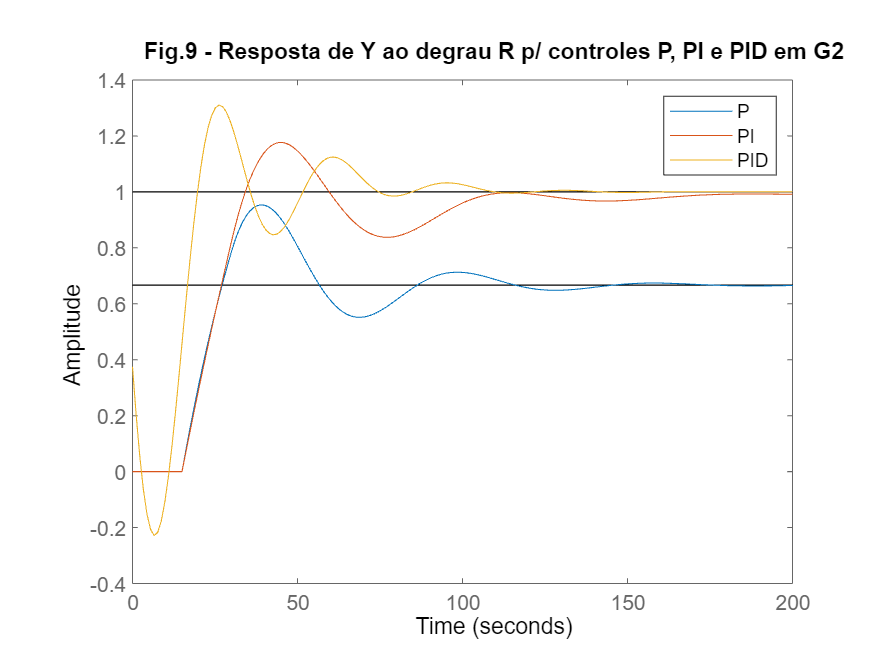

m1=feedback(cp*G2,1);
m2=feedback(cpi*G2,1);
m3=feedback(cpid*G2P,1);

step(m1,m2,m3);legend('P','PI','PID');shg;title('Fig.9 - Resposta de Y ao degrau R p/ controles P, PI e PID em G2');

Comparação em termos de UP, ts e erro em regime:

% CONTROLE P
y_m1=step(m1);
m1_info=stepinfo(m1);
m1_up=m1_info.Overshoot; % UP
m1_ts=m1_info.SettlingTime; % ts
m1_error = 1-y_m1(end); % erro

% CONTROLE PI
y_m2=step(m2);
m2_info=stepinfo(m2);
m2_up=m2_info.Overshoot; % UP
m2_ts=m2_info.SettlingTime; % ts
m2_error = 1-y_m2(end); % erro

% CONTROLE PID
y_m3=step(m3);
m3_info=stepinfo(m3);
m3_up=m3_info.Overshoot; % UP
m3_ts=m3_info.SettlingTime; % ts
m3_error = 1-y_m3(end); % erro


fprintf(['PARA O CONTROLE P:\n' ...
         'Overshoot (UP): %.4f\n' ...
         'Tempo de Estabelecimento (ts): %.4f\n' ...
         'Erro em Regime: %.4f\n\n' ...
         'PARA O CONTROLE PI:\n' ...
         'Overshoot (UP): %.4f\n' ...
         'Tempo de Estabelecimento (ts): %.4f\n' ...
         'Erro em Regime: %.4f\n\n' ...
         'PARA O CONTROLE PID:\n' ...
         'Overshoot (UP): %.4f\n' ...
         'Tempo de Estabelecimento (ts): %.4f\n' ...
         'Erro em Regime: %.4f\n\n'], m1_up, m1_ts, m1_error, m2_up, m2_ts, m2_error, m3_up, m3_ts, m3_error);

PARA O CONTROLE P:
Overshoot (UP): 43.0072
Tempo de Estabelecimento (ts): 135.7286
Erro em Regime: 0.3364

PARA O CONTROLE PI:
Overshoot (UP): 17.6739
Tempo de Estabelecimento (ts): 161.6228
Erro em Regime: 0.0077

PARA O CONTROLE PID:
Overshoot (UP): 31.0163
Tempo de Estabelecimento (ts): 102.1221
Erro em Regime: -0.0027



Dessa forma, o controle PID parece mais interessante, pois possui:

- Erro praticamente zerado;

- Resposta mais rápida (menor ts);

- Menor sobressinal (UP).

3.2) Compare a resposta a um distúrbio Y(s)/D(s) de cada controlador, verificando qual faz a melhor rejeição ao distúrbio, plotando a resposta de P,PI,PID na mesma figura.

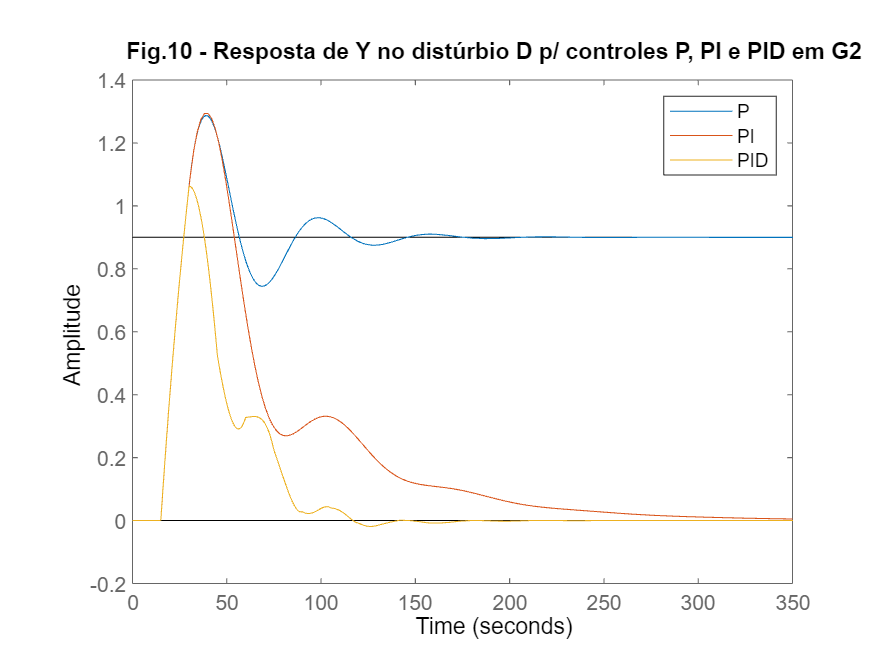

m1d=feedback(G2,cp);
m2d=feedback(G2,cpi);
m3d=feedback(G2,cpid);
step(m1d,m2d,m3d);legend('P','PI','PID');shg;title('Fig.10 - Resposta de Y no distúrbio D p/ controles P, PI e PID em G2');

Tanto PI quanto PID rejeitam o distúrbio, porém, o controle PID faz isso de forma mais rápida. Enquanto isso, o controlador P não possui uma boa rejeição.

**IV) Projeto de controlador PID via métodos de sintonia baseados em modelo**

**Projeto com G2:**

4.1) Seja o modelo G2(s) já definido. Plote em uma mesma figura a resposta ao degrau de G2(s) e de um modelo de referência T(s) que dê a resposta desejada em malha fechada para este processo, de forma que seja mais rápido e sem erro em regime.

G2 % Visualizar G2 já definida

G2 =
 
                 2.7
  exp(-15*s) * --------
               30 s + 1
 
Continuous-time transfer function.
Model Properties


Ao visualizar acima a FT G2 já definida, percebe-se que é uma função de primeira ordem com:

- Tempo morto de 15s;

- Ganho K=2.7;

- Constante de tempo de 30s. 

Portanto, como modelo de referência, desejamos uma resposta mais rápida que essa e sem erro. Para isso, vou definir, por síntese direta, uma função de transferência 'T' com:

- Constante de tempo de 25.5s, seguindo a recomendação de Morari e Zafiriou (1989): λ > 1.7θ para garantir robustez e desempenho;

- Ganho K=1, que elimina o erro;

- Tempo morto de 15s (mantido), pois é fisicamente impossível de ser eliminado.

T=tf(1,[25.5 1]); 
T.InputDelay=15

T =
 
                   1
  exp(-15*s) * ----------
               25.5 s + 1
 
Continuous-time transfer function.
Model Properties


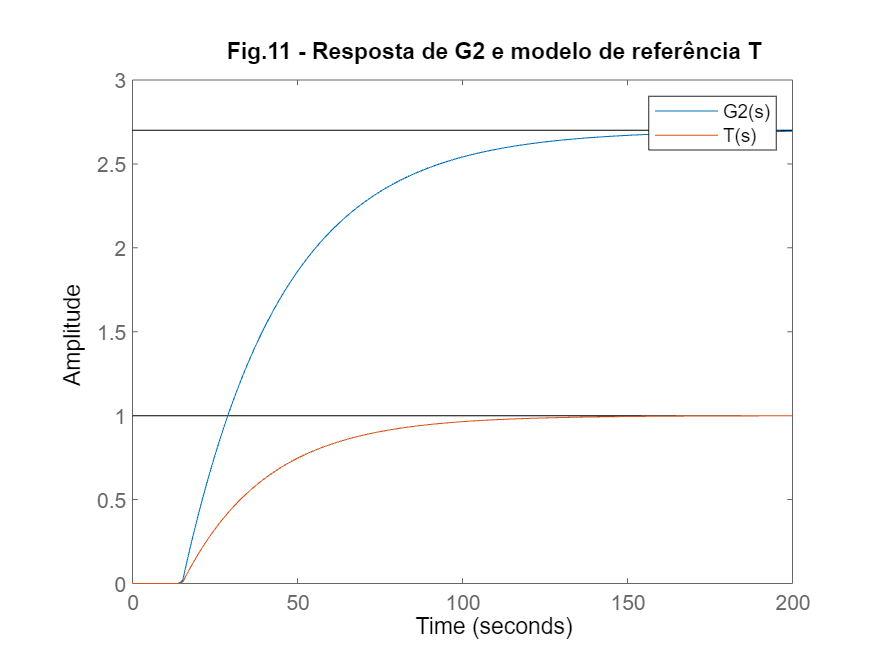

% Plotar em uma mesma figura a resposta ao degrau de G2(s) e modelo T(s)
step(G2,T);legend('G2(s)','T(s)');title ('Fig.11 - Resposta de G2 e modelo de referência T');

Conforme desejado, a resposta do modelo de referência é mais rápida e sem erro em regime.

4.2 Explique as escolhas e os cálculos para obter os parâmetros do controlador C(s) pelo método de síntese direta ou IMC. Obtenha os ganhos do controlador C(s) e plote  no mesmo gráfico a resposta ao degrau do sistema em malha fechada e do modelo de referência T(s), mostrando o atendimento das especificações.

C=pidtuning(G2,'method','lambda','type','PI','param',25.5) % obtem controle C

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.545, Ki = 0.0145
 
Continuous-time PI controller in parallel form.
Model Properties


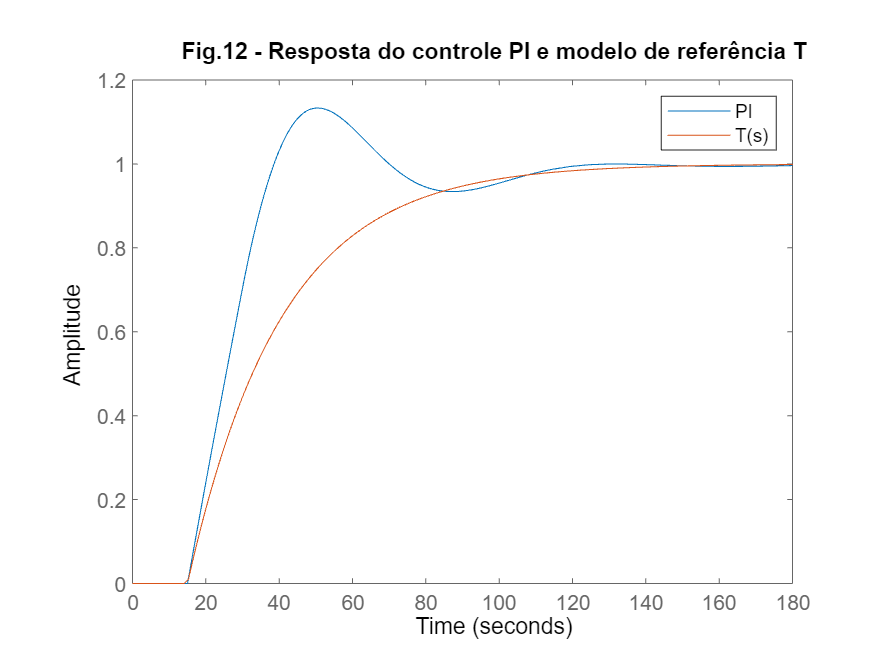

M=feedback(C*G2,1);
step(M,T);legend('PI','T(s)');title('Fig.12 - Resposta do controle PI e modelo de referência T');

Foi usada a função pidtuning para o método lambda, já que se trata de uma 'foptd' e já que esse método atende tanto a síntese direta quanto o IMC. O controlador solicitado foi o PI e os ganhos obtidos foram  Kp=0.545 e Ki=0.0145.

**Projeto com G1:**

4.3 Projete um controlador PID para G1(s) pelo método de síntese direta ou IMC de modo que seu tempo de estabelecimento seja reduzido à metade, com UP<5%.  Plote a saída Y(s) para malha aberta e malha fechada, mostrando o atendimento da especificação, e mostre os valores de UP, ts e IAE.

G1 % visualizar G1 já definida

G1 =
 
         2.3
  ------------------
  320 s^2 + 48 s + 1
 
Continuous-time transfer function.
Model Properties


Para a FT de segunda ordem G1, precisamos obter seu ts.

% FT de segunda ordem sem tempo morto 
G1_info=stepinfo(G1);
fprintf('Tempo de estabelecimento (ts) de G1: %.4fs', G1_info.SettlingTime);

Tempo de estabelecimento (ts) de G1: 165.4084s

Dado o ts para G1, foi solicitado que esse fosse reduzido à metade. Portanto, devemos encontrar um valor de lamda no projeto do PID que faça com que esse tempo fique por volta de 82s (ou melhor).

[C1, iae_C1]=pidtuning(G1,18);
M1=feedback(G1*C1,1);

M1_info=stepinfo(M1);
ts_C1=M1_info.SettlingTime;
up_C1=M1_info.Overshoot;
fprintf('Tempo de estabelecimento (ts) do controle PID: %.4fs', ts_C1);

Tempo de estabelecimento (ts) do controle PID: 70.4173s

O valor de lambda=18 atende à especificação do tempo.

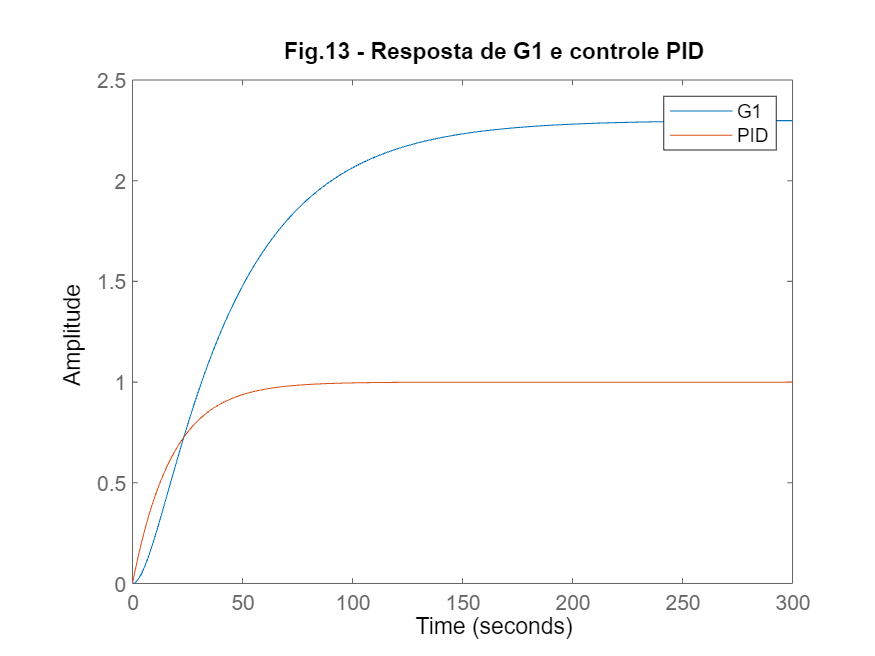

step(G1,M1);legend('G1','PID');title('Fig.13 - Resposta de G1 e controle PID');

Os valores obtidos para atendimento da especificação foram:

fprintf(['Overshoot (UP) = %.4f\n' ...
         'Tempo de Estabelecimento (ts) = %.4fs\n' ...
         'IAE = %.4f\n'], up_C1,ts_C1,iae_C1);

Overshoot (UP) = 0.0000
Tempo de Estabelecimento (ts) = 70.4173s
IAE = 16.8517


4.4 Repita para um controlador PI, explicando a diferença de projeto para o controlador PID, bem como a diferença entre os valores de UP, ts e IAE obtidos aqui e em 4.3

É necessário usar o método polealoc para retornar um PI para uma função de segunda ordem. Esse método requer UP e ts como parâmetro.

Foi exigido que UP seja menor que 5%, dessa forma, colocaremos 4% como parâmetro para o método polealoc e repetiremos o ts obtido no PID da 4.3.

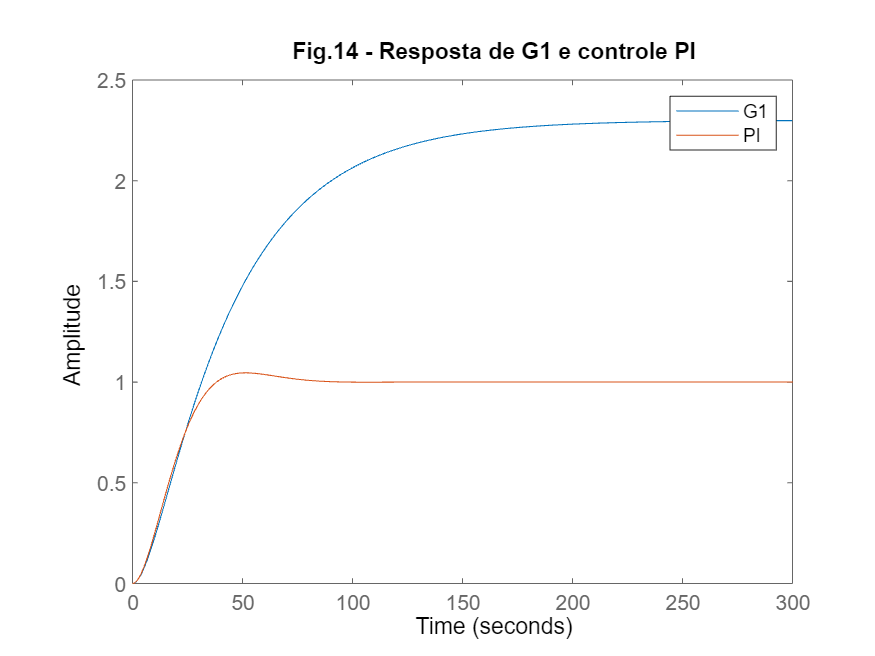

[C2, iae_C2]=pidtuning(G1,'method','polealoc','type','PI','param',[4 70]);
M2=feedback(G1*C2,1);

M2_info=stepinfo(M2);
ts_C2=M2_info.SettlingTime;
up_C2=M2_info.Overshoot;

step(G1,M2);legend('G1','PI');title('Fig.14 - Resposta de G1 e controle PI');

Além de UP e ts já definidos, o valor de IAE obtido foi de:

fprintf('IAE = %.4f\n', iae_C2);

IAE = 19.1124


O controle PID se saiu melhor, pois conseguiu um menor IAE e nenhum sobressinal.

Para finalizar essa comparação, vamos visualizar, no mesmo gráfico, os dois controles obtidos:

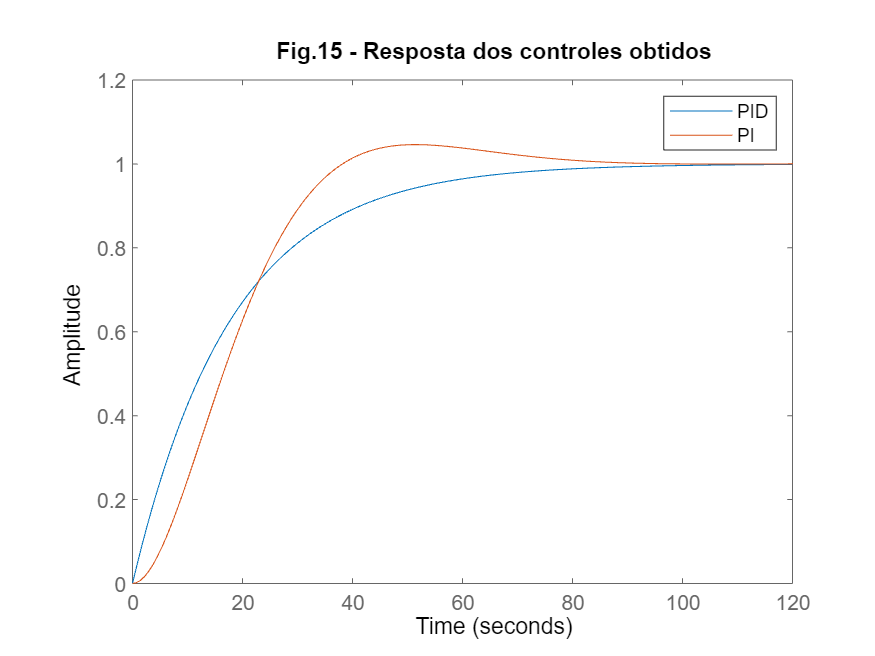

step(M1,M2);legend('PID','PI');title('Fig.15 - Resposta dos controles obtidos');